# Inside the black box

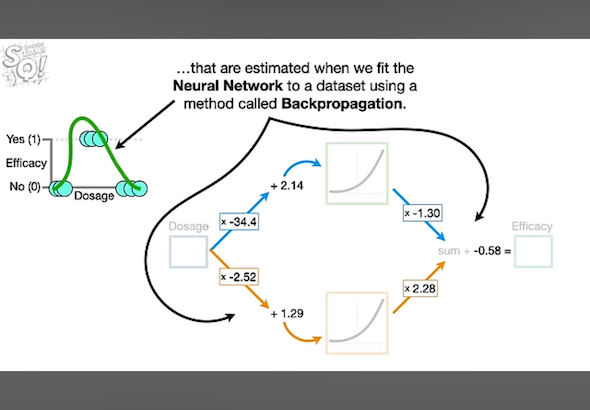

dosage = 0.5;
w = [2.74; -1.13; 0.36; 0.63];
b = zeros(3,1);
observed = [0 1 0];
learningRate = 0.1;
bStep = zeros(3,1);
bDosageDeriv = zeros(3,3);
wStep = zeros(4,1);
stepSize = 10;
wDosageDeriv = zeros(4,3);
howMany = 0;
while abs(stepSize) > 0.005
    dosages = 0:0.5:1;
    [predicted, xs, L1] = getEff(dosages,w,b);
    wDosageDeriv(1:2,:) = -2 .* (observed - predicted) .* w(3:4) .* dact(xs) .* dosages;
    bDosageDeriv(1:2,:) = -2 .* (observed - predicted) .* w(3:4) .* dact(xs);
    wDosageDeriv(3:4,:)= -2 .* (observed - predicted) .* L1;
    bDosageDeriv(3,:) = -2 .* (observed - predicted);

    wDerivSum = sum(wDosageDeriv, 2);
    bDirSum = sum(bDosageDeriv, 2);

    wStep = learningRate * wDerivSum;
    bStep = learningRate * bDirSum;
    stepSize = max([max(abs(bStep)) max(abs(wStep))]);
    b = b - bStep;
    w = w - wStep;
    howMany = howMany+1;
end
howMany

howMany = 398

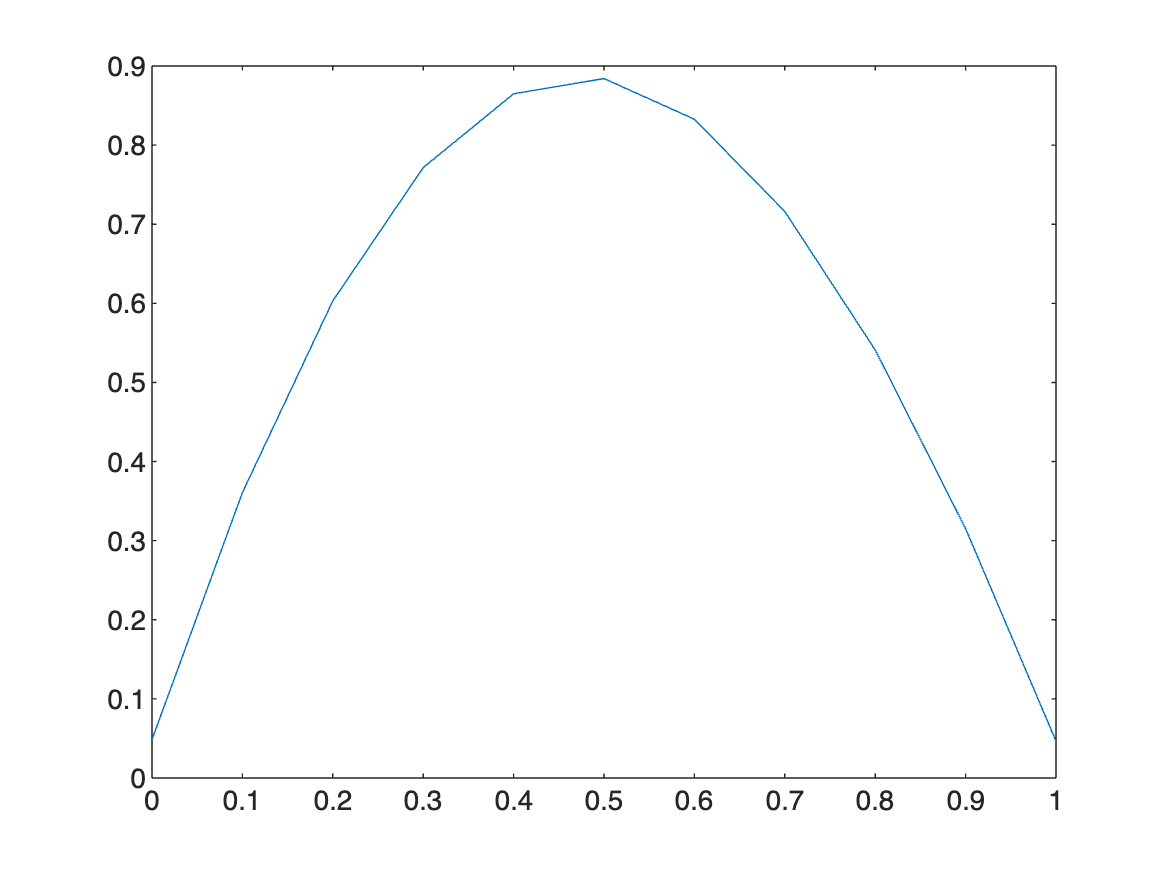

effGraph = getEff(0:0.1:1,w,b);
plot(0:0.1:1, effGraph)


function [efficacy, xs, L1] = getEff(dosage, w, b)
    xs = dosage .* w(1:2,:) + b(1:2,1);
    L1 = softplus(xs);
    blueOrange = L1 .* w(3:4,:);
    greenSquiggle = sum(blueOrange);
    efficacy = greenSquiggle + b(3);
end



## Activation Function

function act = softplus(xx)
    act = log(1+exp(xx));
end

function acto = dact(xx)
    acto = exp(xx) ./ (1 + exp(xx));
end

